In this notebook, we show a simple demo on how to use the provided "run_simulation.m" function to simulate the trajectory of the end-effecotr given a input command (x, y, z coordinates over time). First, we need to define the control signals of the five motors. The control signals are defined as a timeseries object. Please note that:

- motor 1-5 here represents motor 6-2 in the real robot, respectively. The last motor is not considered as it controls the gripper and does not affect the movement of the end-effecotr.

- The control command takes integral values in [0, 1000], which corresponds to [0, 240] degrees. 

In the example below, we simulate a simple movement of the robot. Running the script will give you two Figures. 

- The first one shows the command and response of each motor. 

- The second one shows the command and response of the trajectory of the end-effector. Please note that only the trajectory data are availlable for training the AI model.

- Additionally, you will see an animation of the robot movement.

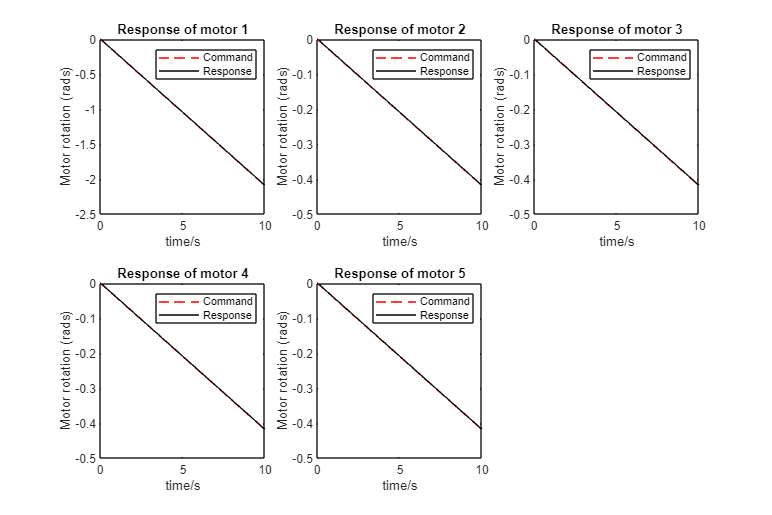

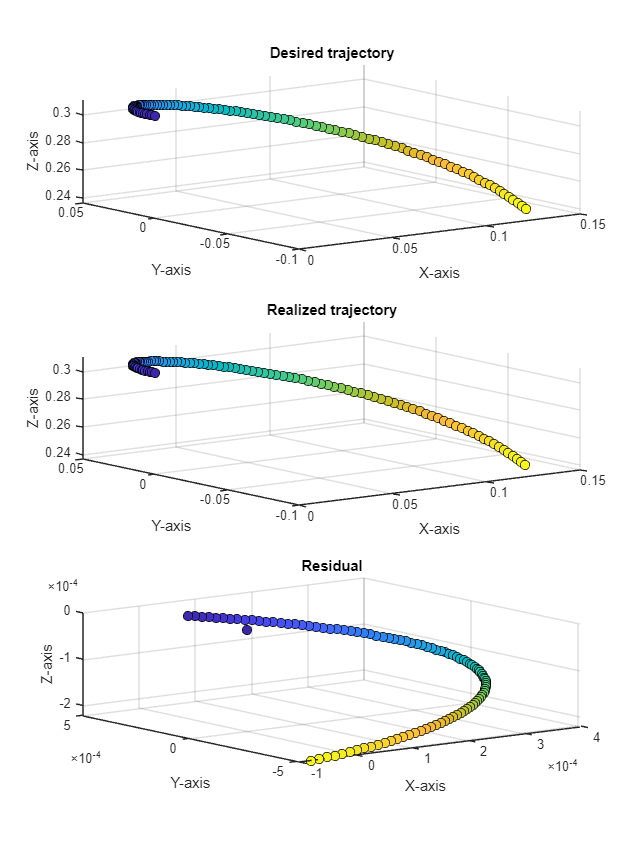

clear; clc; close all;

addpath('../digital_model_complete/')
addpath('../digital_model_kinematics/')

% Define parameters of the simulink model.
mdl_name = 'main3_armpi_fpv.slx';
load_system(mdl_name);

joint1_damping = 0;
joint2_damping = 0;
damp_pince = 1000;

% Generate the time stamps corrsponding to the simulation.
len_time_series = 1000; % Sequence length.
simulation_time = 10; % The time that this sequence corresponds to.
% Calculate the endtime of the sequence.    
end_time_value_in_seconds = (len_time_series-1)*simulation_time/len_time_series; % The time that the last point corresponds to.
% Get the time steps of the sequence.
time_stamps = 0:0.01:end_time_value_in_seconds;

% Let motor 1-5 to move from 500 to 1000 in 10 seconds, respectively.
input_motor_commands = cell(5);
for i = 1:5
    if i == 1
        input_motor_commands{i} = timeseries(linspace(500, 1000, len_time_series), time_stamps);
    else
        input_motor_commands{i} = timeseries(linspace(500, 600, len_time_series), time_stamps);
    end
end

failure_type = 0;
visualization = 1;
[joint_cmds, joint_resps, traj_cmd, traj_resp] = run_simulation(input_motor_commands, failure_type, mdl_name, visualization);

Setting variable `failure_type` from 0 to $1, \cdots, 5$ simulate the stuck failure of motor $1$ to motor $5$, respectivley. You can experiment and see the difference in the realized trajectory. The goal of this project is, then, to use only the system-level condition-monitoring data, i.e., the observed trajectory, for component-level fault diagnosis, i.e., which motor fails and what is the failure mode.

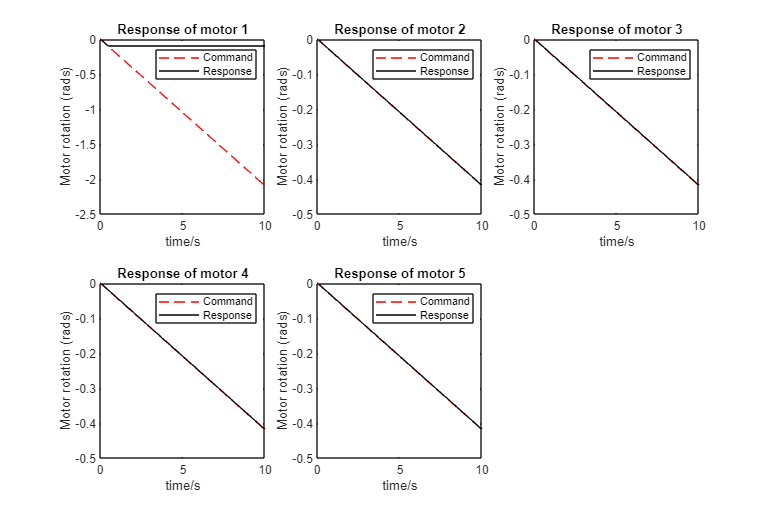

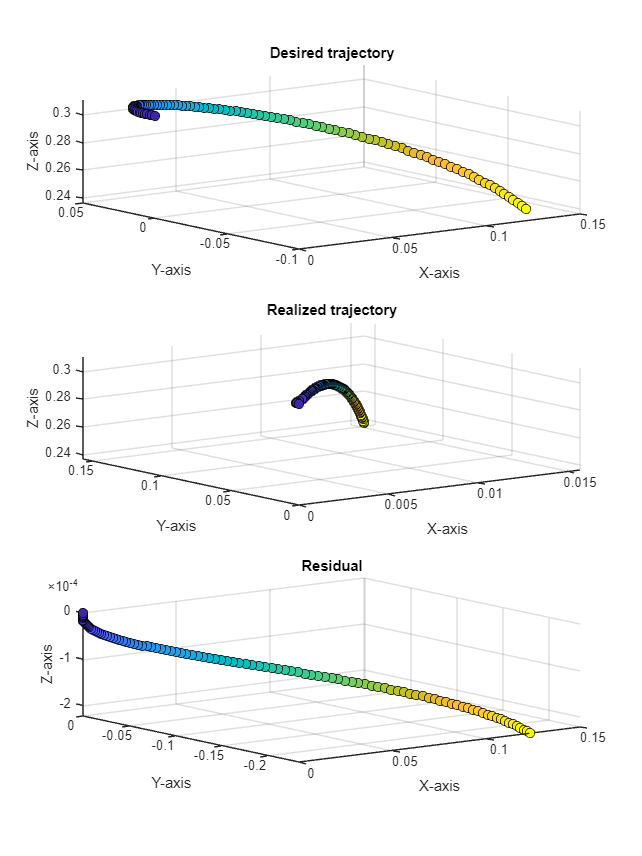

failure_type = 1;
visualization = 1;
[joint_cmds, joint_resps, traj_cmd, traj_resp] = run_simulation(input_motor_commands, failure_type, mdl_name, visualization);